# Testing generated graphs

addpath("functions")
% data Options
do = [1,1];

why is the embedding not calculated as desired?

% [nodes,edges,n,emb,M,P,Cos,Sin] = build("01");
% col1 = [0, 1, 0];
% col2 = [1, 0, 0];
% 
% spy(Cos,'x');
% spy(M)
% gplot(Cos,emb)
% plot(emb(:,1),emb(:,2),".")
% plotColorgradient(2,col1,col2,emb,true,true)

Consider making the directed graph an undirected on from Tristans data. For this we need to check first whether the two edge angles are opposite to each other...

If they are **not, **then we cannot do this! 

If they **are,** then we can savely generate an undirected graph from the data

**EDIT**

The in and out angles should not be the same, as we precisely for this occasion to want to minimize the angular error. The shift of angles over the graph (north direction) should affect the two respective directed edges between two nodes in such way, that the angles do not match...

Check again on this statement!

For visualization: We add up the north shifts of each node to the angles of the outgoing edges of the respective nodes, so we get it drawing accordingly in the graphs! With sufficient north shifts we should be able to see, that the edges do not hit target (the ingoing nodes), as they do in a graph without north shifts...

For this we need to draw not a gplot() graph, as the lines are not drawn according to the angles there:

**EDIT 20210202**

The embeddings either do not get drawn/calculated, as the given graphs and their respective matrices are singular, or the nodes do get embedded in the same spatial position in the graph (see plotCompare("03")) and are not distiguishable, while fulfilling the desired goal of minimizing differences.

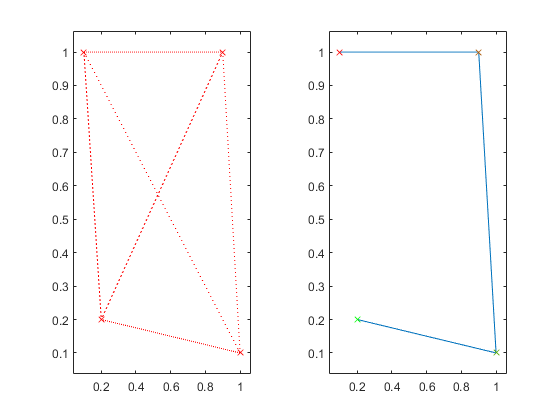

plotTiled("01");

plotTiled("01b");

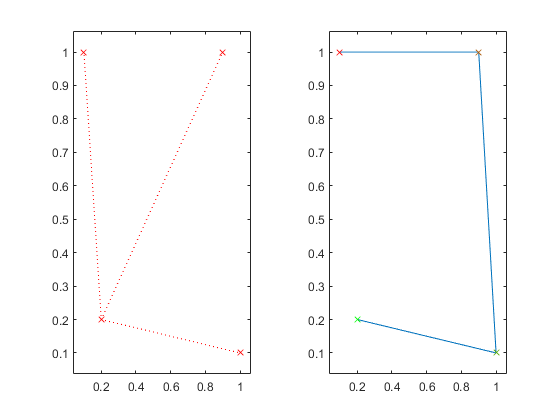

plotTiled("02");

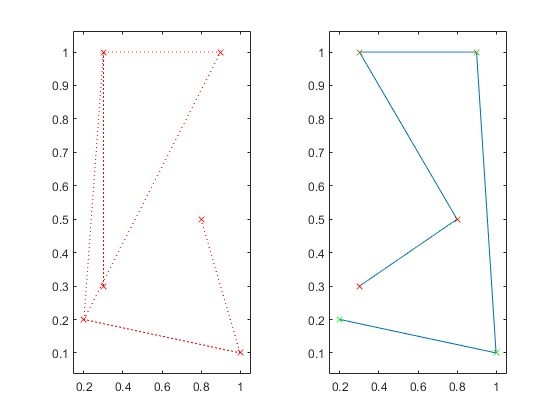

plotTiled("03");

Here we try to draw the nodes and the lines from the nodes to the points, but not from point to point, but from the node at an angle with the fitting length, e.g. the length between the two nodes.

If we choose to reread the data (attribute in **plotCompare()**), we get a warning when the matrix in the embedding calculation is singular. For an example call **build("01")**.


merging...
Elapsed time is 0.004959 seconds.

building M...
Elapsed time is 0.000227 seconds.

building P...
Elapsed time is 0.000073 seconds.


sizeM =      6     3


sizeP =      6     2


rankMM = 3

rankMP = 2

times =     0.0049    0.0002    0.0001


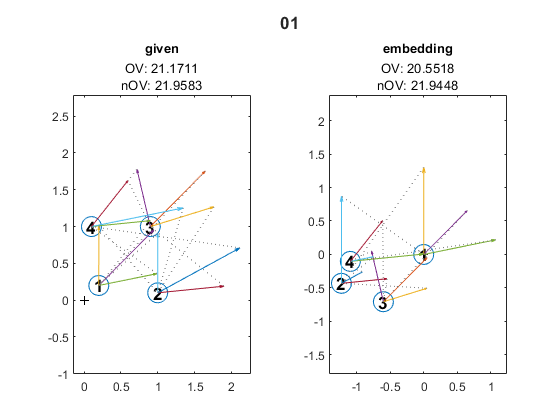

plotCompare("01",do);

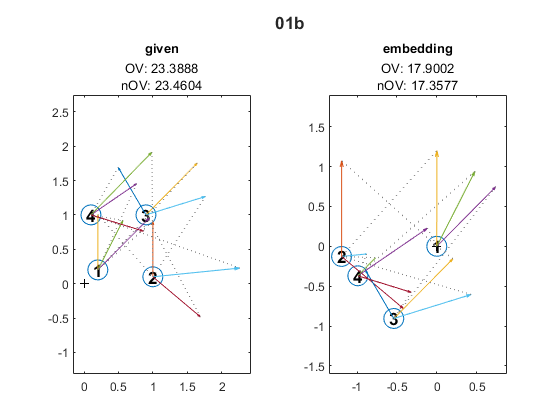


merging...
Elapsed time is 0.002809 seconds.

building M...
Elapsed time is 0.000073 seconds.

building P...
Elapsed time is 0.000050 seconds.


sizeM =      6     3


sizeP =      6     2


rankMM = 3

rankMP = 2

times =     0.0028    0.0001    0.0000


plotCompare("01b",do);

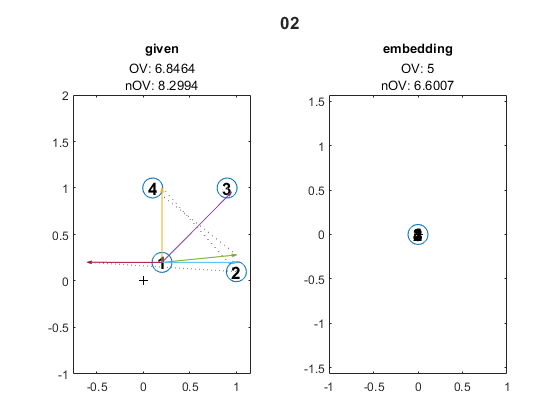


merging...
Elapsed time is 0.002100 seconds.

building M...
Elapsed time is 0.000107 seconds.

building P...
Elapsed time is 0.000058 seconds.


sizeM =      6     3


sizeP =      6     2


rankMM = 3

rankMP = 0

times =     0.0021    0.0001    0.0001


plotCompare("02",do);

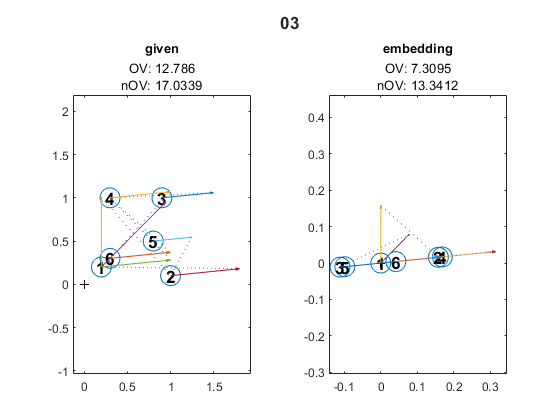


merging...
Elapsed time is 0.002167 seconds.

building M...
Elapsed time is 0.000088 seconds.

building P...
Elapsed time is 0.000051 seconds.


sizeM =     20     5


sizeP =     20     2


rankMM = 5

rankMP = 1

times =     0.0022    0.0001    0.0000


plotCompare("03",do);

This last plot does show what is to be done:

The embedding should result in an arc, as the edges do not form any form of cycles but rather a single path from node **1 **to node **6**. The arc embedding would minimize the differences between the angles.


merging...
Elapsed time is 0.001393 seconds.

building M...
Elapsed time is 0.000110 seconds.

building P...
Elapsed time is 0.000051 seconds.


sizeM =     20     5


sizeP =     20     2


rankMM = 5

rankMP = 2

times =     0.0014    0.0001    0.0000


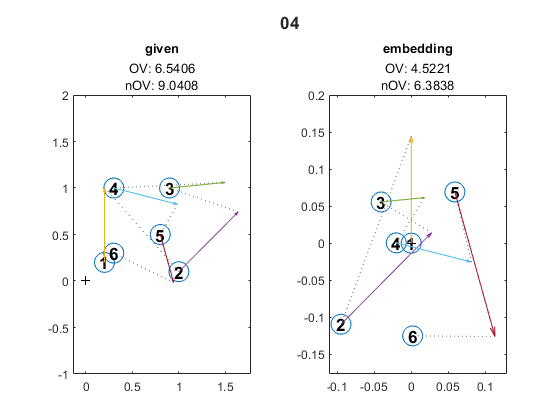

plotCompare("04",do);

While the embedding of **04b** does form a line, node **3** is farthest to the right, while nodes **4** to **6 **seem to inhabit the same positions as at least one other node...

Why does the emedding not form a straight line?

EDIT 20210206

This was updated, so that they dont lay on the same spot anymore, not intentionally, but as a byproduct of changes in **build.m **or others

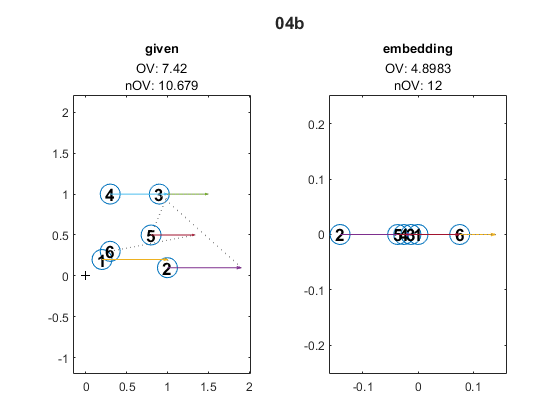


merging...
Elapsed time is 0.001491 seconds.

building M...
Elapsed time is 0.000184 seconds.

building P...
Elapsed time is 0.000047 seconds.


sizeM =     20     5


sizeP =     20     2


rankMM = 5

rankMP = 1

times =     0.0015    0.0002    0.0000


plotCompare("04b",do);

% plotCompareOptions("04b",1,1,0,0,1,0,1,1,do);

With **04c** we generated an initial nearly perfect embedding with a very low OV. Clearly the supposed to be best embedding got a much higher rating on the OV and does not fulfill the desired conditions.

Investigation on this matter will be continued.

What can be stated though, is by comparing **04 **and **04c** we see that the initial embedding of the graph does not matter for the calculated one. What does matter, if we look at **04b** is that the angles do change the embedding.


merging...
Elapsed time is 0.001369 seconds.

building M...
Elapsed time is 0.000096 seconds.

building P...
Elapsed time is 0.000081 seconds.


sizeM =     20     5


sizeP =     20     2


rankMM = 5

rankMP = 2

times =     0.0014    0.0001    0.0001


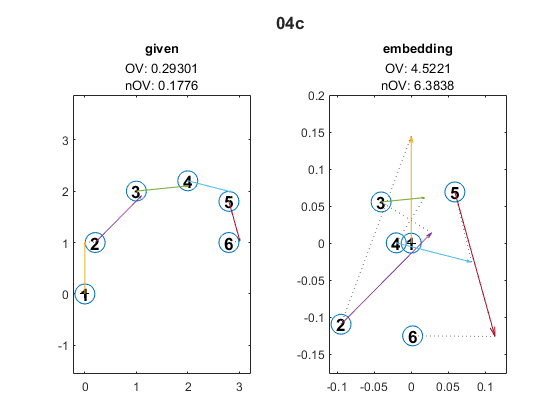

plotCompare("04c",do);

% plotCompareOptions("04c",1,1,0,0,1,0,1,1,do);

In this case the second node should just move slightly to the top right to fit the direction and probably best keep a distance of 1!

Do it...


merging...
Elapsed time is 0.003523 seconds.

building M...
Elapsed time is 0.000443 seconds.

building P...
Elapsed time is 0.000050 seconds.


sizeM =      0     1


sizeP =      0     2


rankMM = 0

rankMP = 0

times =     0.0035    0.0004    0.0000


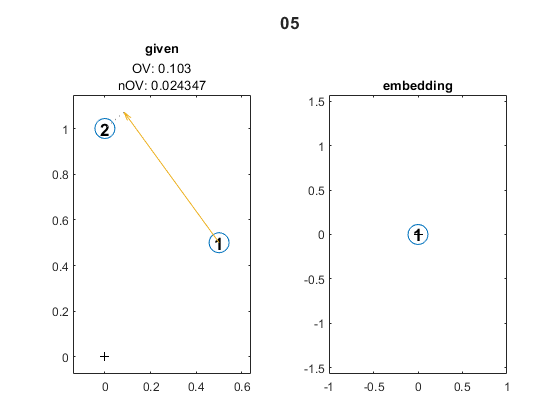

plotCompare("05",do);

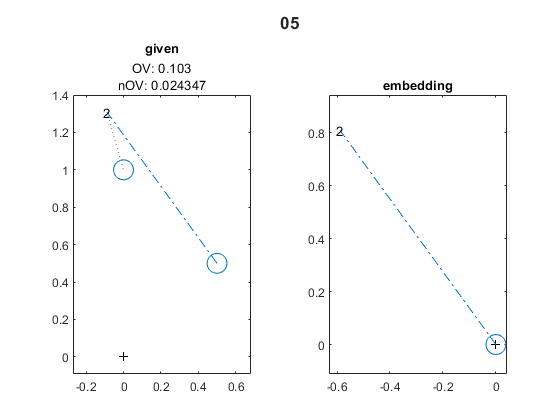


merging...
Elapsed time is 0.000603 seconds.

building M...
Elapsed time is 0.000067 seconds.

building P...
Elapsed time is 0.000049 seconds.


sizeM =      0     1


sizeP =      0     2


rankMM = 0

rankMP = 0

times = 	1.0e+-3 *

    0.5950    0.0629    0.0448


plotCompareOptions("05",1,1,0,0,1,1,1,1,do);


merging...
Elapsed time is 0.000866 seconds.

building M...
Elapsed time is 0.000076 seconds.

building P...
Elapsed time is 0.000061 seconds.


sizeM =      0     1


sizeP =      0     2


rankMM = 0

rankMP = 0

times = 	1.0e+-3 *

    0.8572    0.0714    0.0559


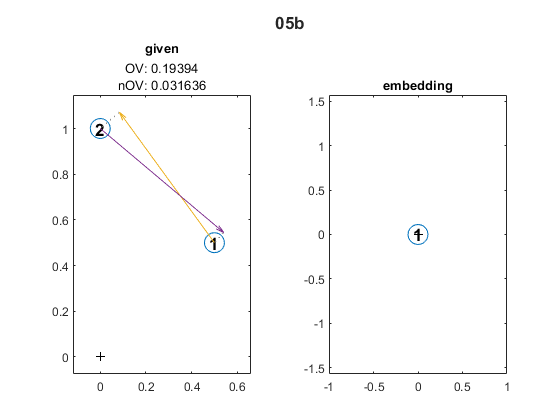

plotCompare("05b",do);

% plotCompareOptions("05b",1,1,0,1,1,0,1,1,do);

This representational graph **06** does kinda do the desired job?! Adding edges does destroy this illusion though... Just lucky then?


merging...
Elapsed time is 0.000529 seconds.

building M...
Elapsed time is 0.000035 seconds.

building P...
Elapsed time is 0.000032 seconds.


sizeM =      2     2


sizeP =      2     2


rankMM = 2

rankMP = 2

times = 	1.0e+-3 *

    0.5254    0.0325    0.0295


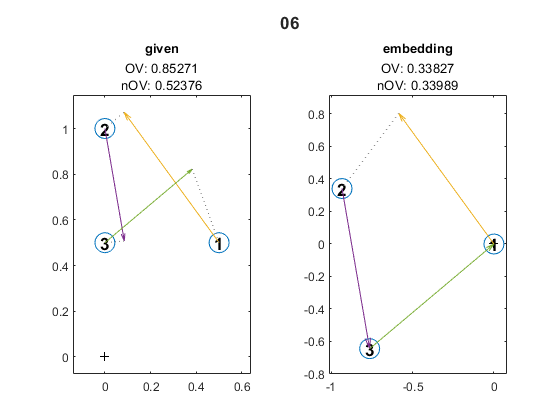

plotCompare("06",do);

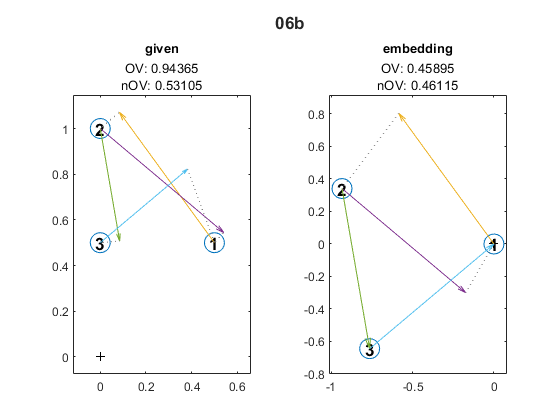


merging...
Elapsed time is 0.001197 seconds.

building M...
Elapsed time is 0.000073 seconds.

building P...
Elapsed time is 0.000084 seconds.


sizeM =      2     2


sizeP =      2     2


rankMM = 2

rankMP = 2

times =     0.0012    0.0001    0.0001


load materials/06.mat emb
emb1 = emb;
% plotCompareOptions("06",1,1,0,0,1,1,1,1,do);
plotCompare("06b",do);

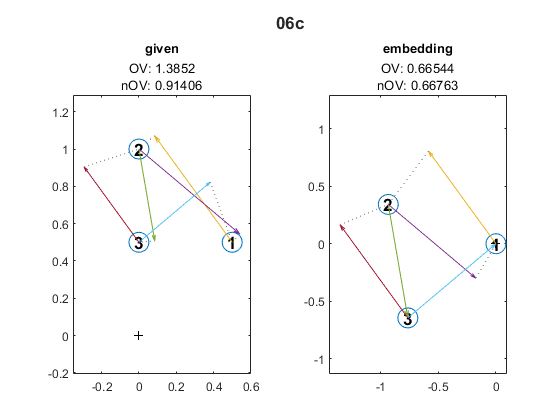


merging...
Elapsed time is 0.000894 seconds.

building M...
Elapsed time is 0.000061 seconds.

building P...
Elapsed time is 0.000058 seconds.


sizeM =      2     2


sizeP =      2     2


rankMM = 2

rankMP = 2

times = 	1.0e+-3 *

    0.8872    0.0570    0.0540


load materials/06b.mat emb
emb2 = emb;
% plotCompareOptions("06b",1,1,0,0,1,1,1,1,do);
plotCompare("06c",do);

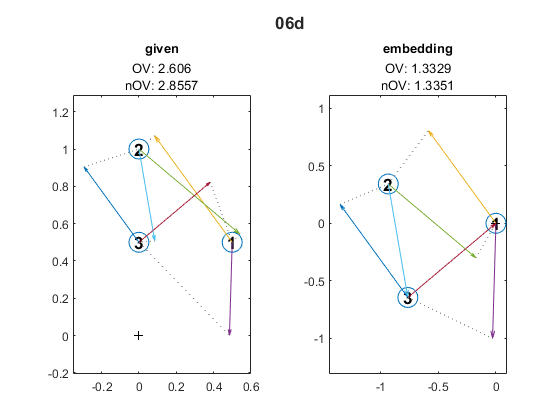


merging...
Elapsed time is 0.000811 seconds.

building M...
Elapsed time is 0.000036 seconds.

building P...
Elapsed time is 0.000025 seconds.


sizeM =      2     2


sizeP =      2     2


rankMM = 2

rankMP = 2

times = 	1.0e+-3 *

    0.8069    0.0344    0.0225


load materials/06c.mat emb
emb3 = emb;
% plotCompareOptions("06c",1,1,0,0,1,1,1,1,do);
plotCompare("06d",do);

load materials/06d.mat emb
emb4 = emb;
% plotCompareOptions("06d",1,1,0,0,1,1,1,1,do);
clear emb

Interestingely enough, there is no difference in embeddings between every version of the **06 **graph. Currently every one got the embedding calculated as

full(emb1)

ans =          0         0
   -0.9348    0.3412
   -0.7648   -0.6442


full(emb2)

ans =          0         0
   -0.9348    0.3412
   -0.7648   -0.6442


full(emb3)

ans =          0         0
   -0.9348    0.3412
   -0.7648   -0.6442


full(emb4)

ans =          0         0
   -0.9348    0.3412
   -0.7648   -0.6442


% is currently
%          0         0
%    -0.9348    0.3412
%    -0.7648   -0.6442

This means, **adding** edges (with variing angles to be noted) does **not change **how the embeddings are calculated.

What **does change **the embeddings is the **angles **though (as seen from example graphs **04**)

Investigate this!!

It seems like the embedding does calculate the perfect embedding only for the edges (from-to-pairs) **2-3** and **3-1**... Same is done by **06** graphs apparently?!


merging...
Elapsed time is 0.000840 seconds.

building M...
Elapsed time is 0.000046 seconds.

building P...
Elapsed time is 0.000034 seconds.


sizeM =      2     2


sizeP =      2     2


rankMM = 2

rankMP = 2

times = 	1.0e+-3 *

    0.8331    0.0437    0.0312


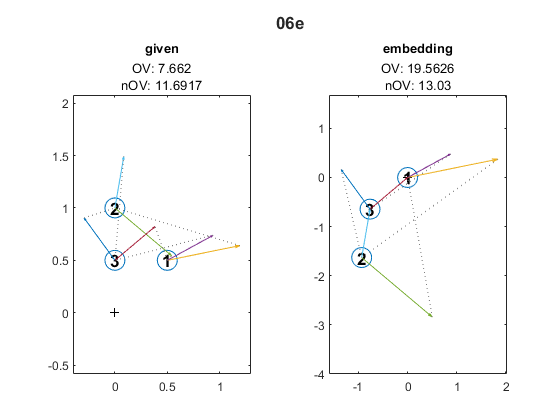

plotCompare("06e",do);